# Acrobot Perturbation Analysis

This script computes the change of coordinates from $(q_u,p_u)$ coordinates into $(\mu,\alpha)$ coordinates for the oscillation area, where

- $\mu = \arccos\left(-\frac{p_u^2}{30m^2gl^3}+\cos(q_u)\right)$ for 

- 
$$\alpha = \arctan_2\left(-\text{sign}(p_u)\sqrt{1 - \frac{q_u^2}{\mu^2}}, \frac{q_u}{\mu}\right)$$


- 
$$q_u = \mu \cos(\alpha)$$


- 
$$p_u = -\text{sign}(\sin(\alpha))\sqrt{30m^2gl^3(\cos(\mu\cos(\alpha))-\cos(\mu))}$$


We apply this to the constrained dynamics under the VNHC $q_a = \bar{q}_a\arctan(I p_u)$ and compute the nominal dynamics under $I = 0$. 

Then (for $I \neq 0$) we scale time to get $\dot{\hat{\mu}} = \frac{\dot{\mu}}{\dot{\alpha}} =: g(\alpha,\hat{\mu},I)$ and perform a perturbation analysis to find $\hat{\mu}(\alpha) \approx \hat{\mu}_0(\alpha) + I \hat{\mu}_1(\alpha)$, where $\hat{\mu}_0(\alpha)$ is the solution to the ODE $\dot{z}_0 = g(\alpha,z_0,0)$ and $\hat{\mu}_1(\alpha)$ is the solution to the ODE $\dot{z}_1 = \frac{\partial g}{\partial \alpha}(\alpha, \hat{\mu}_0(\alpha), 0)z_1 + \frac{\partial g}{\partial I}(\alpha, \hat{\mu}_0(\alpha), 0)$.

clear all
close all
clc;
% Optional code parameters
COMPUTE_ALPHAD_NOM = true; % Programmatically determine nominal alpha_dot 

% Set the dynamic variables for the acrobot
m = sym('m','positive'); % mass
g = sym('g','positive'); % gravity
l = sym('l','positive'); % length
I = sym('I','real'); % VNHC parameter
qb = sym('Q','positive'); % VNHC gain parameter
% Define our coordinates
mu = sym('u','positive'); % pseudo-radius, in ]0,pi[
alpha = sym('a','real'); % pseudo-angle, in ]-pi,pi]
q = sym('q','real'); % unactuated shoulder angle, in ]-pi,pi]
p = sym('p','real'); % unactauted momentum

% Set (qu,pu) as functions of (alpha,mu)
qu = mu*cos(alpha);
pu = -sign(sin(alpha))*...
    sqrt(30*m^2*g*l^3*(cos(mu*cos(alpha)) - cos(mu)));

% Set the actuator symbolically
qa = qb*atan(I*pu);

% Compute the dynamics (qud,pud) as functions of (mu,alpha)
Ipu1 = simplify((1+I^2*pu^2));
su = sin(qu);
sua = sin(qu + qa);
ca = cos(qa);
su2sua = simplify(2*su + sua);
m2gl3 = m^2*g*l^3;

qud = simplify(...
    simplify((Ipu1*pu + m2gl3*qb*I*su2sua*(1+ca))) / ...
    simplify((m*l^2*Ipu1*(3+2*cos(qa)))) ...
    );
pud = simplify(-m*g*l*su2sua);

% Compute mu as a function of qu,pu
Cqp = -p^2/(30*m2gl3) + cos(q);
muqp = simplify(acos(Cqp));

sqm = sqrt(1 - q^2/muqp^2);
% This has a -sign(pu) in front, which is the same as
% +sign(sin(alpha)). We put that after the derivative
% to avoid symbolic errors.
alphaqp = atan(sqm*muqp/q); 

% Compute the dynamcics (mud,alphad)
dmuq = simplify(subs(diff(muqp,q),[q p], [qu pu]));
dmup = simplify(subs(diff(muqp,p),[q p], [qu pu]));
daq = simplify(sign(sin(alpha))*...
    subs(diff(alphaqp,q),[q p],[qu pu]));
dap = simplify(sign(sin(alpha))*...
    subs(diff(alphaqp,p),[q p],[qu pu]));

mud = simplify([dmuq dmup]*[qud;pud]);
alphad = simplify([daq dap]*[qud; pud]);
% Remove errors from symbolic computation
symsToSimplify = [acos(cos(mu)) sign(sin(alpha))^2 ...
         sign(sin(alpha))^4 sign(sin(mu)) ...
         1-cos(mu)^2 1-cos(alpha)^2];
simplifiedValues = [mu 1 1 1 sin(mu)^2 sin(alpha)^2];
for i = 1:5
    mud = simplify(...
        subs(mud, symsToSimplify, simplifiedValues)...
    );
    alphad = simplify(...
        subs(alphad, symsToSimplify, simplifiedValues)...
    );
end

if COMPUTE_ALPHAD_NOM
    % Reduce by setting I = 0
    mud_nom = simplify(subs(mud,I,0));
    alphad_nom = subs(alphad,I,0);
    
    % Remove errors from symbolic computation
    for i = 1:5
        alphad_nom = simplify(...
            subs(alphad_nom, ...
            symsToSimplify, simplifiedValues)...
        );
    end
else
    % If you ran the optional code, you should get the following:
    mud_nom = 0;
    alphad_nom = sqrt(6*g/(5*l))*...
        sqrt((cos(mu*cos(alpha))-cos(mu)) / (mu^2*sin(alpha)^2));
end

% Scale the time and resubstitute to find our function g
gfun = simplify(mud / alphad);

% Get the ODE for mu_1
gdu = simplify(subs(diff(gfun,mu),I,0));
gdI = simplify(subs(diff(gfun,I),I,0));
% Fix simplification errors
gdI = simplify(subs(gdI, symsToSimplify, simplifiedValues));

% The integral of gdu*x1 + gdI at alpha = pi 
% gives us the increase in mu across oscillations.
% Note that gdu = 0, so we can ignore it, and gdI is
% of the form K * Q(alpha,mu) where Q is a-dimensional.
% We compute Q here.
bhat = subs(gdI*15/sqrt(30*m2gl3),[m g l qb],[1 1 1 1]);

mu0s = linspace(0.015,pi-0.05,100);
Q = zeros(size(mu0s));
for i = 1:length(mu0s)
    mu0 = mu0s(i);
    bhatf = matlabFunction(bhat,'vars',[alpha,mu]);
    Q(i) = integral(@(t)bhatf(t,mu0),0,pi);
end

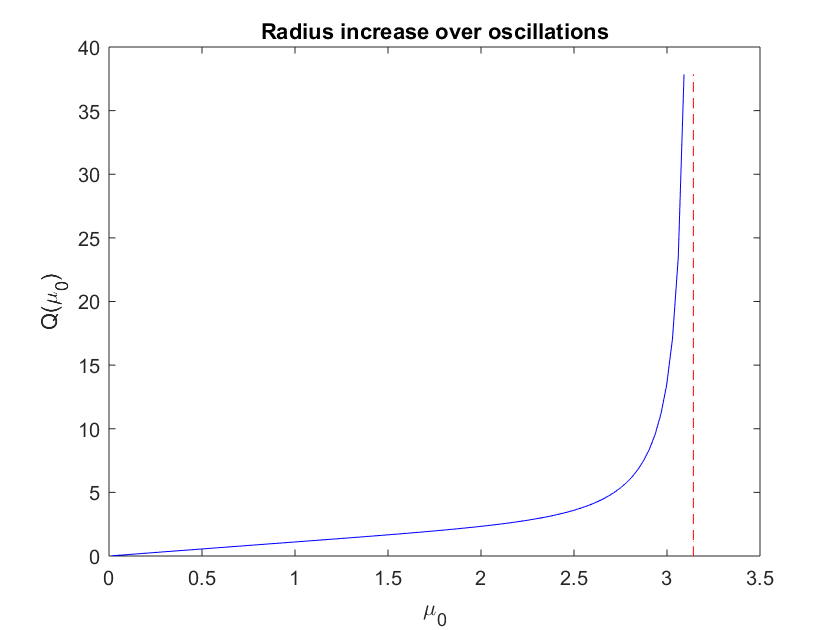

% Display Q(mu) and a vertical red dashed line at mu = pi
piLine = linspace(0,Q(end),100);
pis = ones(1,100).*pi;
Qfig = figure;
plot(mu0s,Q,'b',pis,piLine,'r--');
title('Radius increase over oscillations')
xlabel('\mu_0');
ylabel('Q(\mu_0)');

% Save the file to the folder images/Qmu.png
fname = fullfile(pwd,'thesis_sims','images','Qmu.png');
saveas(Qfig,fname);